|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.35897 |     0.13855 |     0.35897 |     0.35897 |       3.8653 |       961.53 |         true |
|    2 | Best   |     0.13105 |      6.9825 |     0.13105 |     0.15896 |       429.99 |       0.2378 |        false |
|    3 | Accept |     0.35897 |    0.046303 |     0.13105 |     0.13431 |      0.11801 |       8.9479 |        false |
|    4 | Accept |      0.1339 |      3.1921 |     0.13105 |     0.13255 |    0.0010694 |    0.0032063 |         true |
|    5 | Accept |     0.19943 |      8.4922 |   

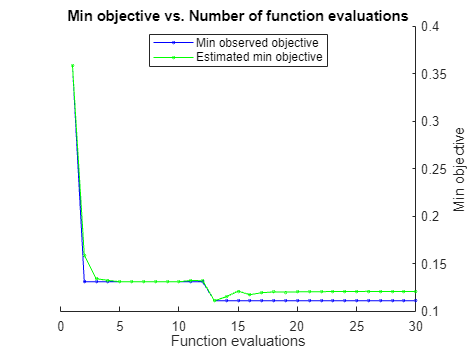

Mdl =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'b'  'g'}
                       ScoreTransform: 'none'
                      NumObservations: 351
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [94×1 double]
                                 Bias: 0.0338
                     KernelParameters: [1×1 struct]
                                   Mu: [0.8917 0 0.6413 0.0444 0.6011 0.1159 0.5501 0.1194 0.5118 0.1813 0.4762 0.1550 0.4008 0.0934 0.3442 0.0711 0.3819 -0.0036 0.3594 -0.0240 0.3367 0.0083 0.3625 -0.0574 0.3961 -0.0712 0.5416 -0.0695 … ] (1×34 double)
                                Sigma: [0.3112 0 0.4977 0.4414 0.5199 0.4608 0.4927 0.5207 0.5071 0.4839 0.5635 0.4948 0.6222 0.4949 0.6528 0.4584 0.6180 0.4968 0.6263 0.5191 0.6098 0.5182 0.6038 0.5275 0.5785 0.5085 0.5162 0.550

% 优化 SVM 分类器
% 使用 fitcsvm 自动优化超参数。
% 
% 加载 ionosphere 数据集。

load ionosphere
% 通过使用自动超参数优化，找到最小化五折交叉验证损失的超参数。
% 为了实现可再现性，请设置随机种子并使用 'expected-improvement-plus' 采集函数。

rng default
Mdl = fitcsvm(X,Y,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
    'expected-improvement-plus'))